# PID Synthesis of Motor 2

T = 0.02;
z = tf('z', T);
s = tf('s');

Gpz = ((1.033*z^(2) + 0.004355*z - 0.2917)/(z^(3) - 1.171*z^(2) + 0.348*z))

Gpz =
 
  1.033 z^2 + 0.004355 z - 0.2917
  -------------------------------
     z^3 - 1.171 z^2 + 0.348 z
 
Sample time: 0.02 seconds
Discrete-time transfer function.



Gps = d2c(Gpz, 'tustin')

Gps =
 
  -0.2926 s^3 - 75.92 s^2 + 7558 s + 2.96e05
  ------------------------------------------
     s^3 + 151.8 s^2 + 5879 s + 7.027e04
 
Continuous-time transfer function.



Gps_2 = (4.2*exp(-0.0155*s))/(0.0435*s+1)

Gps_2 =
 
                       4.2
  exp(-0.0155*s) * ------------
                   0.0435 s + 1
 
Continuous-time transfer function.



Gpz_2 = c2d(Gps_2, T,'zoh')

Gpz_2 =
 
           0.4128 z + 1.135
  z^(-1) * ----------------
              z - 0.6314
 
Sample time: 0.02 seconds
Discrete-time transfer function.



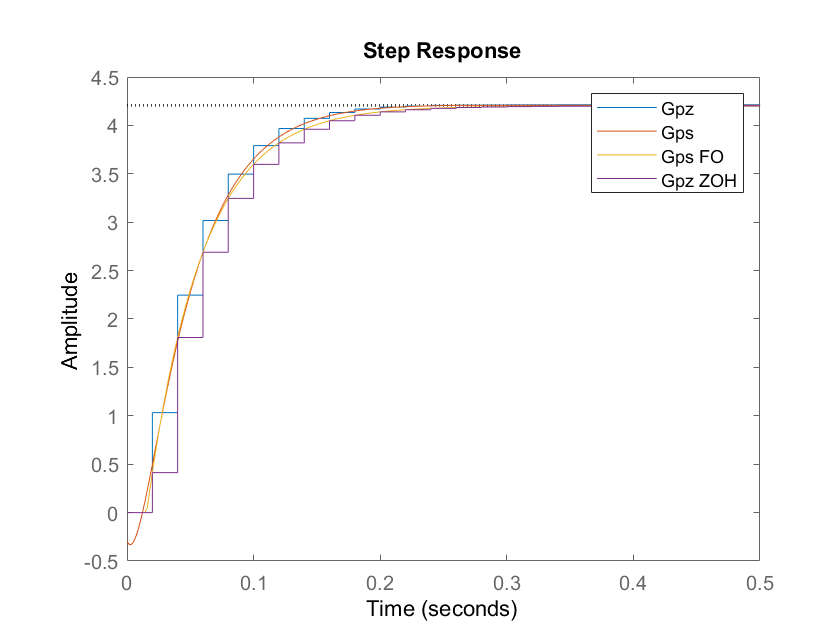

step(Gpz)
hold on
step(Gps)
step(Gps_2)
step(Gpz_2)
legend('Gpz', 'Gps','Gps FO', 'Gpz ZOH')
hold off

For the the first order transfer function in continuous time, a two point analysis of the Motor 2 transfer function was made to determine the K, Tau and Theta values. 


$$\textrm{Gp}\left(s\right)=\frac{{\textrm{Ke}}^{\theta s} }{\tau s+1}$$



$$K=\;x;$$



$$\tau =\;x;$$



$$\theta =\;x;$$


%Computing of the PID paramters (ITAE)
K = 4.2;
Tau = 0.0435;
Theta = 0.0155;

%ITAE
%{
a = 0.965;
b = -0.85;
c = 0.796;
d = -0.147;
e = 0.308;
f = 0.929;
%}
%IAE
a = 1.086;
b = -0.869;
c = 0.74;
d = -0.13;
e = 0.348;
f = 0.914;

Kp = (1/K)*(a*(Theta/Tau)^b);
Taui = (Tau)/(c+d*(Theta/Tau));
Taud = (Tau)*(e*(Theta/Tau)^f);

Kpz = Kp-(Kp*T)/(2*Taui)

Kpz = 0.5328

Kiz = (Kp*T)/Taui

Kiz = 0.2022

Kdz = (Kp*Taud)/T

Kdz = 0.1868